% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=x^3; T=2*pi; [-pi;pi]

clear
pi1=pi;
syms x real;
syms pi;
f(x)=x^3;

syms m integer;
assume(m>=1)
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = 0$$

$$a(m) = 0$$

$$b(m) = \frac{{\left(-1\right)}^{m+1}\,\left(2\,m^{2}\,\pi^{2}-12\right)}{m^{3}}$$

$$abf(m) = \frac{{\left(-1\right)}^{m+1}\,\sin\left(m\,x\right)\,\left(2\,m^{2}\,\pi^{2}-12\right)}{m^{3}}$$

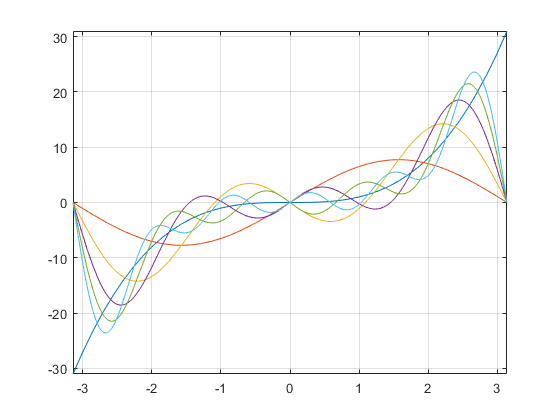


fplot(f(x),[-pi1 pi1]);
grid on
hold on

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-pi1 pi1])
    grid on
end
hold off


a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 1 & 0 & \sigma_{1} & \sin\left(x\right)\,\sigma_{1}\\ 2 & 0 & \frac{3}{2}-\pi^{2} & -\frac{\sin\left(2\,x\right)\,\left(8\,\pi^{2}-12\right)}{8}\\ 3 & 0 & \frac{2\,\pi^{2}}{3}-\frac{4}{9} & \frac{\sin\left(3\,x\right)\,\left(18\,\pi^{2}-12\right)}{27}\\ 4 & 0 & \frac{3}{16}-\frac{\pi^{2}}{2} & -\frac{\sin\left(4\,x\right)\,\left(32\,\pi^{2}-12\right)}{64}\\ 5 & 0 & \frac{2\,\pi^{2}}{5}-\frac{12}{125} & \frac{\sin\left(5\,x\right)\,\left(50\,\pi^{2}-12\right)}{125} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\pi^{2}-12 \end{array}$$

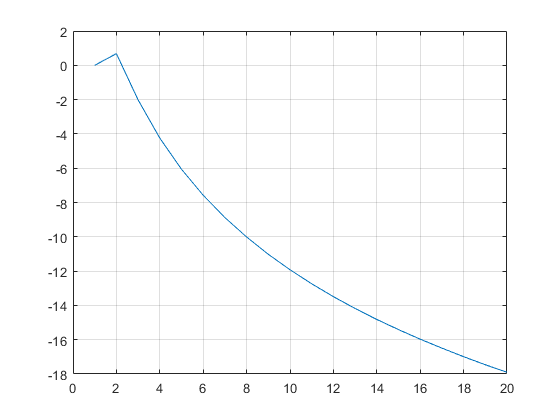

% [ 1, 0,         2*pi^2 - 12,          sin(x)*(2*pi^2 - 12)]
% [ 2, 0,          3/2 - pi^2,   -(sin(2*x)*(8*pi^2 - 12))/8]
% [ 3, 0,    (2*pi^2)/3 - 4/9,  (sin(3*x)*(18*pi^2 - 12))/27]
% [ 4, 0,       3/16 - pi^2/2, -(sin(4*x)*(32*pi^2 - 12))/64]
% [ 5, 0, (2*pi^2)/5 - 12/125, (sin(5*x)*(50*pi^2 - 12))/125]

x=0:20;
y(1)=a0/2;
for m=1:20
    y(m+1)=a(m)+1i*b(m);
end
yd=20*log10(abs(y)/abs(y(2)));

plot(x,yd)
grid on;